# Create and Train a Deep Learning Model

Script for creating and training a deep learning network with the following properties:

Run this script to create the network layers, import training and validation data, and train the network. The network layers are stored in the workspace variable `layers`. The trained network is stored in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 23-Jul-2020 18:54:54

## Load Initial Parameters

Load parameters for network initialization. For transfer learning, the network initialization parameters are the parameters of the initial pretrained network.

trainingSetup = load("C:\Users\pablo\Documents\UNIVERSIDAD\TFG_Neural_Network\MatLab\MisCosas\MatLab-TFG-Neural-Network\LineaBola2\trainingSetup_2020_07_23__18_54_47.mat");

## Import Data

Import training and validation data.

imdsTrain = imageDatastore("C:\Users\pablo\Documents\UNIVERSIDAD\TFG_Neural_Network\MatLab\MisCosas\MatLab-TFG-Neural-Network\LineaBola2\imgLineaBolaDoble","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain,0.7);

## Augmentation Settings

imageAugmenter = imageDataAugmenter(...
    "RandXReflection",true,...
    "RandYReflection",true);

% Resize the images to match the network input layer.
augimdsTrain = augmentedImageDatastore([100 100 1],imdsTrain,"DataAugmentation",imageAugmenter);
augimdsValidation = augmentedImageDatastore([100 100 1],imdsValidation);

## Set Training Options

Specify options to use when training.

opts = trainingOptions("sgdm",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",0.01,...
    "MaxEpochs",60,...
    "Shuffle","every-epoch",...
    "ValidationFrequency",10,...
    "Plots","training-progress",...
    "ValidationData",augimdsValidation);

## Create Array of Layers

layers = [
    imageInputLayer([100 100 1],"Name","imageinput")
    convolution2dLayer([3 3],8,"Name","conv_1","Padding","same")
    maxPooling2dLayer([2 2],"Name","maxpool_1","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    convolution2dLayer([3 3],16,"Name","conv_2","Padding","same")
    maxPooling2dLayer([2 2],"Name","maxpool_2","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")
    convolution2dLayer([3 3],32,"Name","conv_3","Padding","same")
    maxPooling2dLayer([2 2],"Name","maxpool_3","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_3")
    convolution2dLayer([3 3],64,"Name","conv_4","Padding","same")
    maxPooling2dLayer([2 2],"Name","maxpool_4","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_4")
    reluLayer("Name","relu_4")
%     convolution2dLayer([3 3],128,"Name","conv_5","Padding","same")
%     maxPooling2dLayer([2 2],"Name","maxpool_5","Padding","same","Stride",[2 2])
%     batchNormalizationLayer("Name","batchnorm_5")
%     reluLayer("Name","relu_5")
    fullyConnectedLayer(3,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## Train Network

Train the network using the specified options and training data.

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:01 |       32.03% |       46.67% |       1.7600 |       1.2688 |          0.0100 |


|      10 |          10 |       00:00:09 |       77.34% |       74.44% |       0.4637 |       0.6734 |          0.0100 |


|      20 |          20 |       00:00:19 |       96.88% |       87.78% |       0.1698 |       0.3076 |          0.0100 |


|      30 |          30 |       00:00:29 |       97.66% |       94.44% |       0.0758 |       0.1866 |          0.0100 |


|      40 |          40 |       00:00:39 |      100.00% |       97.78% |       0.0291 |       0.0965 |          0.0100 |


|      50 |          50 |       00:00:48 |      100.00% |       96.67% |       0.0126 |       0.0778 |          0.0100 |


|      60 |          60 |       00:00:58 |      100.00% |       96.67% |       0.0104 |       0.0784 |          0.0100 |


|======================================================================================================================|


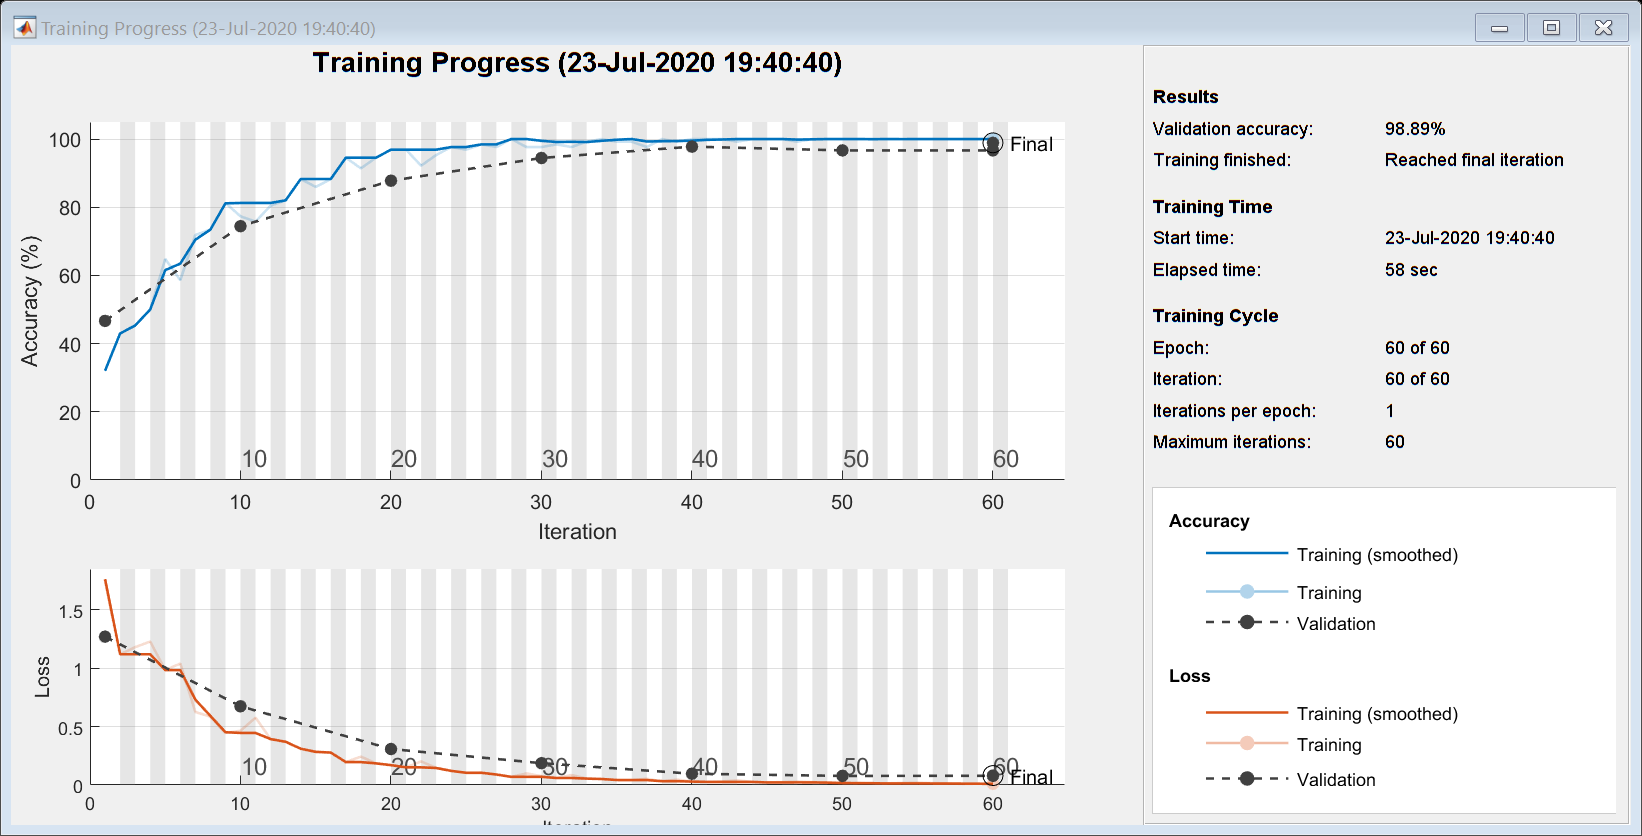

[net, traininfo] = trainNetwork(augimdsTrain,layers,opts);

## Save Results

save resultados1 net imdsTrain imdsValidation layers opts